# Traffic Sign Recognition 

This example shows how to train a a model to recognize German traffic signs using deep learning. 

## Overview

Traffic sign detection and recognition are important applications of ADAS (Advanced Driver Assistance Systems) in providing information to the driver about road signs. 

This example uses the public domain dataset GTSRB (German Traffic Sign Recognition Benchmark) which can be found [here](https://www.kaggle.com/datasets/meowmeowmeowmeowmeow/gtsrb-german-traffic-sign). It is a single-image, multi-class classification problem with more than 40 classes and over 50,000 images. 

## Load Dataset

This example uses a subset of the images (about 40,000). Each image is associated with one label, or one German traffic sign. The data is contained within a folder which has subfolders corresponding to each label. 

Load the data into an imageDatastore, including subfolders and assigning labels based on subfolder names. Determine number of classes.

data = imageDatastore('Train','IncludeSubfolders',true,'LabelSource','foldernames');
numClasses = length(unique(data.Labels));

Display a few random image examples.

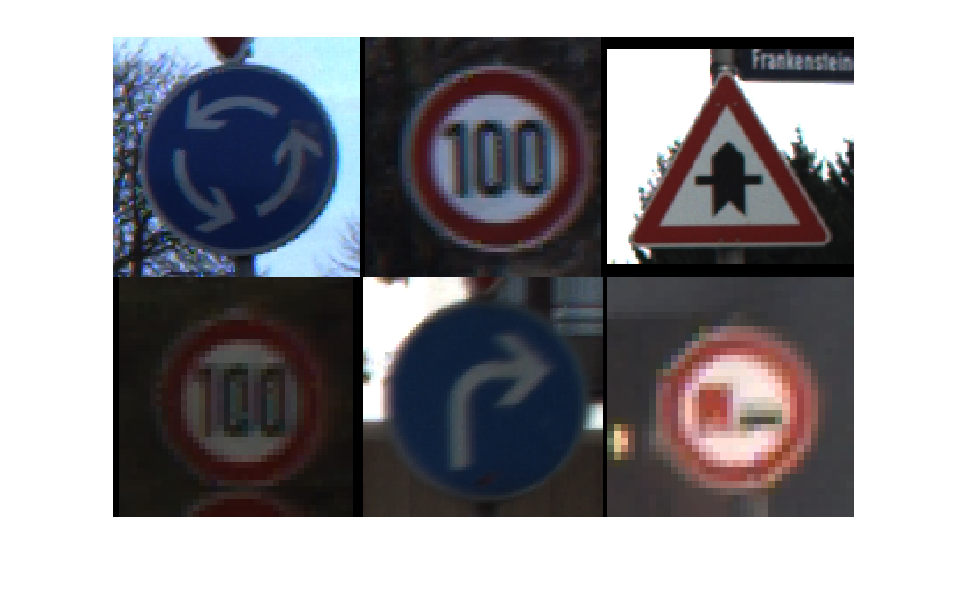

randomImgs = cell(6,1);
for i = 1:6
    randomImgs{i} = readimage(data,randi(numel(data.Files)));
end
montage(randomImgs)

## Dataset Preprocessing 

Split the data set into a training set for training the model and a test set for evaluating the model. Select 70% of the data for training, and use the rest for evaluation. The 'randomized' parameter randomly assigns the specified proportion of files from each label to the new datastores. 

[trainData, testData] = splitEachLabel(data,0.7,'randomized');

Some images may vary in size, so reshape the data so that it is uniform prior to training. 

imageSize = [30 30 3];
trainDataResized = augmentedImageDatastore(imageSize, trainData);
testDataResized = augmentedImageDatastore(imageSize, testData);

## Define Network Architecture

Convolution Neural Networks (CNNs) are commonly used for image recognition. The layers below outline a simple architecture for classification. 

layers = [
    imageInputLayer([30 30 3])

%     convolution2dLayer(5,16,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(5,32,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(5,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## Train Network

Define training options using `trainingOptions. `

options = trainingOptions('adam', ...
    'MiniBatchSize', 128, ...
    'MaxEpochs', 5, ...
    'Verbose', true);
net = trainNetwork(trainDataResized, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        2.34% |      15.5008 |          0.0010 |
|       1 |          50 |       00:00:03 |       41.41% |       8.0615 |          0.0010 |
|       1 |         100 |       00:00:06 |       62.50% |       5.2057 |          0.0010 |
|       1 |         150 |       00:00:08 |       61.72% |       5.7210 |          0.0010 |
|       1 |         200 |       00:00:11 |       71.88% |       3.6330 |          0.0010 |
|       2 |         250 |       00:00:13 |       68.75% |       4.1240 |          0.0010 |
|       2 |         300 |  

## Test Network

Classify the images in the test dataset and compare the predicated labels to their actual labels. 

predictedLabels = classify(net,testDataResized);
actualLabels = testData.Labels;
accuracy = sum(predictedLabels == actualLabels) / length(actualLabels);
fprintf('Classification accuracy is %f', accuracy)

Classification accuracy is 0.791125